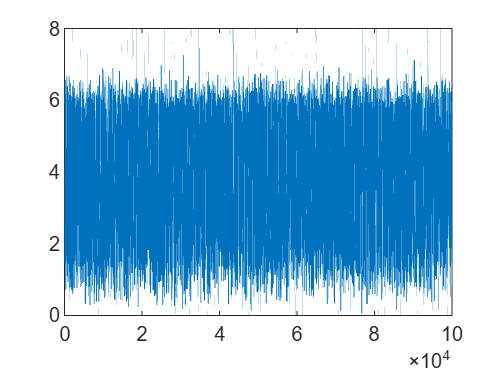

M = 2;              % Number of transmit antennas
P = 10;             % Transmit power
N = 1e5;            % Number of realizations


h_real = normrnd(0,1,[N M]) / sqrt(2);
h_imag = normrnd(0,1,[N M]) / sqrt(2);

h = h_real + 1j * h_imag;

norm_h_squared = sum(abs(h).^2, 2);

R = log2(1 + P * norm_h_squared);

plot(R);